% Intervallo di integrazione
nuspan = linspace(0.001, 1, 100);
e0 = 2; % maximum firing rate [spike/s]
r = 1; % steepness of the sigmoid function
nu0 = 0.1; % postsynaptic potential for which half of the maximum firing rate is achieved 

SS = e0 ./ (1 - exp(r.*(nu0 - nuspan)));

% Plot della soluzione x(t)
figure;
plot(nuspan, SS, 'b-', 'LineWidth', 2);
grid on;
xlabel('Presynaptic input');
ylabel('Membrane potential');
title('Potenziale di membrana in fuznione di input');

% Risoluzione e visualizzazione della ODE:
% d^2x/dt^2 + (2/tau_e)dx/dt + (1/tau_e^2)x = Asin(t)

tau_e = 0.01;
A = 10;

% Sistema equivalente
odefun = @(t, X) [X(2); sin(t) + (2/tau_e)*X(2) - (1/(tau_e^2))*X(1)];

% Intervallo di integrazione
tspan = [0 0.100];

% Condizioni iniziali [x(0); x'(0)]
X0 = [0; 0];   % ad esempio x(0)=0, x'(0)=0

% Risoluzione numerica
[t, X] = ode45(odefun, tspan, X0);

% Estrazione delle soluzioni
x = X(:,1);
dx = X(:,2);

% Plot della soluzione x(t)
figure;
plot(t, x, 'b-', 'LineWidth', 2);
grid on;
xlabel('Tempo t');
ylabel('x(t)');
title('Soluzione di d^2x/dt^2 + dx/dt + x = sin(t)');

% (opzionale) confronto con sin(t) per vedere la forzante
hold on;
plot(t, sin(t), 'r--', 'LineWidth', 1.5);
legend('x(t)', 'sin(t)');
hold off;

% Risoluzione e visualizzazione della ODE:
% d^2x/dt^2 = - x

tau_e = 0.01;
A = 10;

% Sistema equivalente
odefun = @(t, X) [X(2); - X(1)];

% Intervallo di integrazione
tspan = [0 10];

% Condizioni iniziali [x(0); x'(0)]
X0 = [1; 1];   % ad esempio x(0)=0, x'(0)=0

% Risoluzione numerica
[t, X] = ode45(odefun, tspan, X0);

% Estrazione delle soluzioni
x = X(:,1);
dx = X(:,2);

% Plot della soluzione x(t)
figure;
plot(t, x, 'b-', 'LineWidth', 2);
grid on;
xlabel('Tempo t');
ylabel('x(t)');

%Risoluzione e visualizzazione del neurotoxicity model con l'obietivo di
%andare a vedere cosa accade alle costanti del modello JR quando c'è
%propagazione di Abeta e tau
%partiamo innanzitutto dal definire le costanti che ci servono
prod_AB = 3;
clear_AB = 3;
trans_AB = 3; 
clear_ABtilde = 2.4;
prod_T = 3;
clear_T = 3;
trans_T = 3; 
clear_Ttilde = 2.55;
syn = 0.4;
rho = 50;
c_q_ABtilde = 1;
c_q_Ttilde = 1;
c_q_ha = 0.01;
c_exc_ABtilde = 0.8;
c_inh_ABtilde = 0.4;
c_exc_Ttilde = 1.8;
c_inh_Ttilde = 1.8;
c_sc_Ttilde = 0.05;
H_e_max = 3.65;
C_ip_min = 13.25;
C_ep_min = 28;
sc_dam = 0.3;
q_max_ha = 2;
Delta_ha = 0.5; % mean regional firing rate [spike/s] during the proteinopaty over
% mean reference (healty) value (sarebbe da simulare, per ora ho inserito 1/2 come prova, poi vediamo)

%prima di tutto guardiamo cosa succede all'evoluzione dell'accumulo di
%proteine in un solo nodo. Da qui possiamo anche dedurre valori inziali per

%adesso ci servono dei valori iniziali
X0 = [100; % AB, tentativo che mi sembra ragionevole %22e-12 
    1; % ABtilde, dedotto dal grafico nell'articolo di Alvarez
    100; % T, tentativo che mi sembra ragionevole %10e-12
    0.1; % Ttilde, dedotto dal grafico nell'articolo di Alvarez
    0.5; % q_ha, punto fisso
    3.25; % H_e, tabulato nell'articolo di Alvarez
    33.75; % C_ip, tabulato nell'articolo di Alvarez
    108; % C_ep, tabulato nell'articolo di Alvarez
    0.0; % q_ABtilde, dedotto dal grafico nell'articolo di Alvarez
    0.0]; % q_Ttilde, dedotto dal grafico nell'articolo di Alvarez

%dal codice di Alvarez otteniamo questo:
%ABt_initMap = [0.05 / len(AB_seeds) if roi in AB_seeds else 0 for roi in conn.region_labels]
%TAUt_initMap = [0.005 / len(TAU_seeds) if roi in TAU_seeds else 0 for roi in conn.region_labels]
%AB_initdam, TAU_initdam = [[0 for roi in conn.region_labels]] * 2
%HA_initdam = [1 for roi in conn.region_labels]
%dalla quale deduciamo i seguenti valori iniziali

X0 = [1; % AB, dal codice di Alvarez 
    0.0; % ABtilde, dal codcie di Alvarez
    1; % T, dal codcie di Alvarez
    0.0; % Ttilde, dal codcie di Alvarez
    1; % q_ha, dal codcie di Alvarez
    3.25; % H_e, tabulato nell'articolo di Alvarez
    33.75; % C_ip, tabulato nell'articolo di Alvarez
    108; % C_ep, tabulato nell'articolo di Alvarez
    0.0; % q_ABtilde, dal codcie di Alvarez
    0.0]; % q_Ttilde, dal codcie di Alvarez

%dal codice di Alvarez vediamo che le proteine tossiche partono da 0.05 e
%0.005 nelle regioni interessate e da 0 nelle altre
ABtilde0 = 0.05;
Ttilde0 = 0.005;

mean_weight = -1.92;
odefun = @(t, X) [-rho*mean_weight*X0(1) + prod_AB*X(5) - clear_AB*X(1)      - trans_AB*X(1)*X(2); % AB_1
                  -rho*mean_weight*ABtilde0             - clear_ABtilde*X(2) + trans_AB*X(1)*X(2); % ABtilde_1
                  -rho*mean_weight*X0(3) + prod_T       - clear_T*X(3)       - trans_T*X(3)*X(4) - syn*X(2)*X(3)*X(4); % T_1
                  -rho*mean_weight*Ttilde0*X(5)         - clear_Ttilde*X(4)  - trans_T*X(3)*X(4) - syn*X(2)*X(3)*X(4); % Ttilde_1
                  c_q_ha*(-X(5) + Delta_ha)*(q_max_ha - X(5))*X(5); % q_ha_1
                  c_exc_ABtilde*X(9)*(H_e_max - X(6)); % H_e_1
                  -c_inh_ABtilde*X(9)*(X(7) - C_ip_min) - c_inh_Ttilde*X(10)*(X(7) - C_ip_min); % C_ip_1
                  -c_exc_Ttilde*X(10)*(X(8) - C_ep_min); % C_ep_1
                  c_q_ABtilde*X(2)*(1 - X(9)); % q_ABtilde_1
                  c_q_Ttilde*X(4)*(1 - X(10)); % q_Ttilde_1
                ];

% Intervallo di integrazione
tspan = [0 4]; %anni

[t, X] = ode45(odefun, tspan, X0);

% Estrazione delle soluzioni
AB_1 = X(:,1);
ABtilde_1 = X(:,2);
T_1 = X(:,3);
Ttilde_1 = X(:,4);
q_ha_1 = X(:,5); 
H_e_1 = X(:,6);
C_ip_1 = X(:,7);
C_ep_1 = X(:,8);
q_ABtilde_1 = X(:,9);
q_Ttilde_1 = X(:,10);

% Plot di AB_1
figure;
plot(t, AB_1, 'b-', 'LineWidth', 2);
grid on;
xlabel('Time [years]');
ylabel('AB_1');

% Plot di ABtilde_1
figure;
plot(t, ABtilde_1, 'b-', 'LineWidth', 2);
grid on;
xlabel('Time [years]');
ylabel('ABtilde_1');

% Plot di T_1
figure;
plot(t, T_1, 'g-', 'LineWidth', 2);
grid on;
xlabel('Time [years]');
ylabel('T_1');

% Plot di Ttilde_1
figure;
plot(t, Ttilde_1, 'm-', 'LineWidth', 2);
grid on;
xlabel('Time [years]');
ylabel('Ttilde_1');

% Plot di q_ha_1
figure;
plot(t, q_ha_1, 'c-', 'LineWidth', 2);
grid on;
xlabel('Time [years]');
ylabel('q_ha_1');
title('Evoluzione di q_{ha,1} nel modello di neurotossicità');

% Plot di H_e_1
figure;
plot(t, H_e_1, 'k-', 'LineWidth', 2);
grid on;
xlabel('Time [years]');
ylabel('H_e_1');
title('Evoluzione di H_e_1 nel modello di neurotossicità');

% Plot di C_ip_1
figure;
plot(t, C_ip_1, 'b-', 'LineWidth', 2);
grid on;
xlabel('Time [years]');
ylabel('C_ip_1');

% Plot di C_ep_1
figure;
plot(t, C_ep_1, 'm-', 'LineWidth', 2);
grid on;
xlabel('Time [years]');
ylabel('C_ep_1');

% Plot di q_ABtilde_1
figure;
plot(t, q_ABtilde_1, 'r-', 'LineWidth', 2);
grid on;
xlabel('Time [years]');
ylabel('q_ABtilde_1');

% Plot di q_Ttilde_1
figure;
plot(t, q_Ttilde_1, 'r-', 'LineWidth', 2);
grid on;
xlabel('Time [years]');
ylabel('q_Ttilde_1');

tic
%Risoluzione e visualizzazione del neurotoxicity model con l'obietivo di
%andare a vedere cosa accade alle costanti del modello JR quando c'è
%propagazione di Abeta e tau
%partiamo innanzitutto dal definire le costanti che ci servono
prod_AB = 3;
clear_AB = 3;
trans_AB = 3; 
clear_ABtilde = 2.4;
prod_T = 3;
clear_T = 3;
trans_T = 3; 
clear_Ttilde = 2.55;
syn = 0.4;
rho = 50;
c_q_ABtilde = 1;
c_q_Ttilde = 1;
c_q_ha = 0.01;
c_exc_ABtilde = 0.8;
c_inh_ABtilde = 0.4;
c_exc_Ttilde = 1.8;
c_inh_Ttilde = 1.8;
c_sc_Ttilde = 0.05;
H_e_max = 3.65;
C_ip_min = 13.25;
C_ep_min = 28;
sc_dam = 0.3;
q_max_ha = 2;
Delta_ha = 0.5; % mean regional firing rate [spike/s] during the proteinopaty over
% mean reference (healty) value (sarebbe da simulare, per ora ho inserito 1/2 come prova, poi vediamo)
mean_weight = 0.0192;
mean_self_weight = 0.0181;

                  % -rho*mean_weight*X0(1) + prod_AB*X(5) - clear_AB*X(1)      - trans_AB*X(1)*X(2); % AB_1
                  % -rho*mean_weight*ABtilde0             - clear_ABtilde*X(2) + trans_AB*X(1)*X(2); % ABtilde_1
                  % -rho*mean_weight*X0(3) + prod_T       - clear_T*X(3)       - trans_T*X(3)*X(4) - syn*X(2)*X(3)*X(4); % T_1
                  % -rho*mean_weight*Ttilde0*X(5)         - clear_Ttilde*X(4)  - trans_T*X(3)*X(4) - syn*X(2)*X(3)*X(4); % Ttilde_1
                  % c_q_ha*(-X(5) + Delta_ha)*(q_max_ha - X(5))*X(5); % q_ha_1
                  % c_exc_ABtilde*X(10)*(H_e_max - X(6)); % H_e_1
                  % -c_inh_ABtilde*X(9)*(X(7) - C_ip_min) - c_inh_Ttilde*X(10)*(X(7) - C_ip_min); % C_ip_1
                  % -c_exc_Ttilde*X(10)*(X(8) - C_ep_min); % C_ep_1
                  % c_q_ABtilde*X(2)*(1 - X(9)); % q_ABtilde_1
                  % c_q_Ttilde*X(4)*(1 - X(10)); % q_Ttilde_1

odefun = @(t, X) [rho.*(X(9).*X(12) - X(23).*X(1)) + prod_AB.*X(5)  - clear_AB.*X(1)      - trans_AB.*X(1).*X(2); % AB_1
                  %-rho(-w_12*AB2+w_11*AB1) + prodAB*qha1 - clearAB*AB1 - transAB*AB*Abtilde
                  rho.*(X(9).*X(13) - X(23).*X(2))                  - clear_ABtilde*X(2) + trans_AB*X(1)*X(2); % ABtilde_1
                  %-rho(-w_12*AB2tilde+w_11*AB1tilde) - clearABtilde*AB1tilde + transAB*AB*Abtilde
                  rho.*(X(9).*X(14) - X(23).*X(3)) + prod_T         - clear_T.*X(3)       - trans_T.*X(3).*X(4) - syn.*X(2).*X(3).*X(4); % T_1
                  %-rho(-w_12*T2+w_11*T1) + prodT - clearT*T1 - transT*T*Ttilde - syn*AB1tilde*T1*T1tilde
                  rho.*X(5).*(X(9).*X(15) - X(23).*X(4))            - clear_Ttilde*X(4)  + trans_T*X(3)*X(4) + syn*X(2)*X(3)*X(4); % Ttilde_1
                  %-rho.*qha1(-w_12*T2tilde+w_11*T1tilde) - clearTtilde*Ttilde1 + transT*T*Ttilde + syn*AB1tilde*T1*T1tilde
                  c_q_ha.*(-X(5) + Delta_ha).*(q_max_ha - X(5)).*X(5); % q_ha_1
                  %cqha1*(-qha1 + deltaha)*(qhamax - qha1)*qha1
                  c_exc_ABtilde.*X(10).*(H_e_max - X(6)); % H_e_1
                  %cexcABtilde*qABtilde1(Hemax - He1)
                  -c_inh_ABtilde.*X(10).*(X(7) - C_ip_min) - c_inh_Ttilde.*X(11).*(X(7) - C_ip_min); % C_ip_1
                  -c_exc_Ttilde.*X(11).*(X(8) - C_ep_min); % C_ep_1
                  -c_sc_Ttilde.*(X(11) + X(22)).*(X(9) - mean_weight.*(1 - sc_dam)); % w_12
                  c_q_ABtilde.*X(2).*(1 - X(10)); % q_ABtilde_1
                  c_q_Ttilde.*X(4).*(1 - X(11)); % q_Ttilde_1
                  rho.*(X(20).*X(1) - X(24).*X(12)) + prod_AB.*X(16) - clear_AB.*X(12)      - trans_AB.*X(12).*X(13); % AB_2
                  rho.*(X(20).*X(2) - X(24).*X(13))                  - clear_ABtilde*X(13) + trans_AB*X(12)*X(13); % ABtilde_2
                  rho.*(X(20).*X(3) - X(24).*X(14)) + prod_T         - clear_T.*X(14)       - trans_T.*X(14).*X(15) - syn.*X(13).*X(14).*X(15); % T_2
                  rho.*X(16).*(X(20).*X(4) - X(24).*X(15))           - clear_Ttilde*X(15)  + trans_T*X(14)*X(15) + syn*X(13)*X(14)*X(15); % Ttilde_2
                  c_q_ha.*(-X(16) + Delta_ha).*(q_max_ha - X(16)).*X(16); % q_ha_2
                  c_exc_ABtilde.*X(21).*(H_e_max - X(17)); % H_e_2
                  -c_inh_ABtilde.*X(21).*(X(18) - C_ip_min) - c_inh_Ttilde.*X(22).*(X(18) - C_ip_min); % C_ip_2
                  -c_exc_Ttilde.*X(22).*(X(19) - C_ep_min); % C_ep_2
                  -c_sc_Ttilde.*(X(22) + X(11)).*(X(20) - mean_weight.*(1 - sc_dam)); % w_21
                  c_q_ABtilde.*X(13).*(1 - X(21)); % q_ABtilde_2
                  c_q_Ttilde.*X(15).*(1 - X(22)); % q_Ttilde_2
                  -c_sc_Ttilde.*(X(11) + X(11)).*(X(23) - mean_self_weight.*(1 - sc_dam)); % w_11
                  -c_sc_Ttilde.*(X(22) + X(22)).*(X(24) - mean_self_weight.*(1 - sc_dam)); % w_22
                ];

%adesso ci servono dei valori iniziali
%dal codice di Alvarez vediamo che le proteine tossiche partono da 0.05 e
%0.005 nelle regioni interessate e da 0 nelle altre
X0 = [1; % AB, dal codice di Alvarez 
    0.0; % ABtilde, dal codcie di Alvarez
    1; % T, dal codcie di Alvarez
    0.0; % Ttilde, dal codcie di Alvarez
    1; % q_ha, dal codcie di Alvarez
    3.25; % H_e, tabulato nell'articolo di Alvarez
    33.75; % C_ip, tabulato nell'articolo di Alvarez
    108; % C_ep, tabulato nell'articolo di Alvarez
    mean_weight; % w_12, connettività media di TVB_connetivity_76
    0.0; % q_ABtilde, dal codcie di Alvarez
    0.0; % q_Ttilde, dal codcie di Alvarez
    1; % AB, dal codice di Alvarez 
    0.05; % ABtilde, dal codcie di Alvarez
    1; % T, dal codcie di Alvarez
    0.005; % Ttilde, dal codcie di Alvarez
    1; % q_ha, dal codcie di Alvarez
    3.25; % H_e, tabulato nell'articolo di Alvarez
    33.75; % C_ip, tabulato nell'articolo di Alvarez
    108; % C_ep, tabulato nell'articolo di Alvarez
    mean_weight; % w_12, connettività media di TVB_connetivity_76
    0.0; % q_ABtilde, dal codcie di Alvarez
    0.0; % q_Ttilde, dal codcie di Alvarez
    mean_self_weight; % w_11, auto_connettività media di TVB_connetivity_76
    mean_self_weight]; % w_11, auto_connettività media di TVB_connetivity_76


% Intervallo di integrazione
tspan = linspace(0, 100, 100000); %anni
dt = 100/100000;

opts = odeset('RelTol',1e-4,'AbsTol',1e-6);
[t, X] = ode23s(odefun, tspan, X0);

toc

Elapsed time is 0.649172 seconds.


% Estrazione delle soluzioni
inizio = 1;
fine = 1;
AB_1 = X(inizio:end-fine,1);
ABtilde_1 = X(inizio:end-fine,2);
T_1 = X(inizio:end-fine,3);
Ttilde_1 = X(inizio:end-fine,4);
q_ha_1 = X(inizio:end-fine,5); 
H_e_1 = X(inizio:end-fine,6);
C_ip_1 = X(inizio:end-fine,7);
C_ep_1 = X(inizio:end-fine,8);
w_12 = X(inizio:end-fine,9);
q_ABtilde_1 = X(inizio:end-fine,10); 
q_Ttilde_1 = X(inizio:end-fine,11);
AB_2 = X(inizio:end-fine,12);
ABtilde_2 = X(inizio:end-fine,13);
T_2 = X(inizio:end-fine,14);
Ttilde_2 = X(inizio:end-fine,15);
q_ha_2 = X(inizio:end-fine,16); 
H_e_2 = X(inizio:end-fine,17);
C_ip_2 = X(inizio:end-fine,18);
C_ep_2 = X(inizio:end-fine,19);
w_21 = X(inizio:end-fine,20);
q_ABtilde_2 = X(inizio:end-fine,21);
q_Ttilde_2 = X(inizio:end-fine,22);
w_11 = X(inizio:end-fine,23);
w_22 = X(inizio:end-fine,24);
times = t(inizio:end-fine);

Ttilde1_max = max(Ttilde_1);
thresholdT = Ttilde1_max / 10;

% Trova il primo indice in cui x supera la soglia
idx = find(Ttilde_1 > thresholdT, 1, 'first');

% Interpolazione lineare per una stima più precisa
if idx > 1
    T1 = Ttilde_1(idx-1);  T2 = Ttilde_1(idx);
    t1 = t(idx-1);  t2 = t(idx);
    t_crossT = t1 + (thresholdT - T1) * (t2 - t1) / (T2 - T1)
else
    t_crossT = t(idx);  % nel caso superi la soglia già al primo punto
end

t_crossT = 4.0042


ABtilde1_max = max(ABtilde_1);
thresholdAB = ABtilde1_max / 10;

% Trova il primo indice in cui x supera la soglia
idx = find(ABtilde_1 > thresholdAB, 1, 'first');

% Interpolazione lineare per una stima più precisa
if idx > 1
    AB1 = ABtilde_1(idx-1);  AB2 = ABtilde_1(idx);
    t1 = t(idx-1);  t2 = t(idx);
    t_crossAB = t1 + (thresholdAB - AB1) * (t2 - t1) / (AB2 - AB1)
else
    t_crossAB = t(idx);  % nel caso superi la soglia già al primo punto
end

t_crossAB = 0.5864


H_e_1_max = max(H_e_1);
H_e_1_min = min(H_e_1);
thresholdH_e_1 = H_e_1_min + (H_e_1_max - H_e_1_min) * 0.9;

% Trova il primo indice in cui x supera la soglia
idx = find(H_e_1 > thresholdH_e_1, 1, 'first');

t_crossH_e_1 = t(idx)  % nel caso superi la soglia già al primo punto

t_crossH_e_1 = 8.6391


w_12_max = max(w_12);
w_12_min = min(w_12);
thresholdw_12 = w_12_min + (w_12_max - w_12_min) * 0.1;

% Trova il primo indice in cui x supera la soglia
idx = find(w_12 < thresholdw_12, 1, 'first');

t_crossw_12 = t(idx)  % nel caso superi la soglia già al primo punto

t_crossw_12 = 33.7043


ABstages = t_crossH_e_1/t_crossAB

ABstages = 14.7334

Tstages = t_crossw_12/t_crossT

Tstages = 8.4172

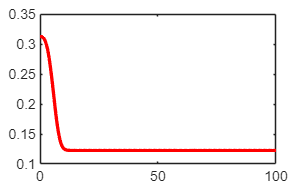


plot(times(1: end-1), C_ip_1(1: end-1)/C_ep_1(1), 'r-', 'LineWidth', 2, DisplayName='C_{ip,1}');

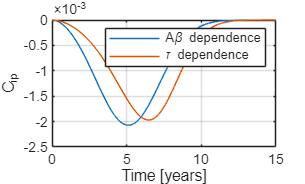

figure;
plot(times(1: end-1), (times(2:end) - times(1:end-1)) .* (-c_inh_ABtilde.*q_ABtilde_1(1:end-1).*(C_ip_1(1:end-1) - C_ip_min)), DisplayName='A\beta dependence')
hold on;
plot(times(1: end-1), (times(2:end) - times(1:end-1)) .* (-c_inh_Ttilde.*q_Ttilde_1(1:end-1).*(C_ip_1(1:end-1) - C_ip_min)), DisplayName='\tau dependence')
hold off;
grid on;
legend;
xlim([0, 15])
xlabel('Time [years]');
ylabel('C_{ip}');

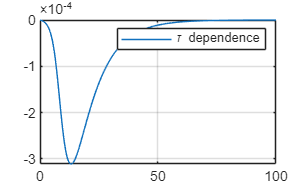


plot(times(1:end), -c_sc_Ttilde.*(q_Ttilde_1 + q_Ttilde_2).*(w_12 - mean_weight.*(1 - sc_dam)), DisplayName='\tau dependence')
legend;
grid on;
hold off;

w_12_delta = w_12(1)-w_12(end);% valore iniziale
w_12(1)

ans = 0.0192

w_12(end)

ans = 0.0134

w_11(1)

ans = 0.0181

w_11(end)

ans = 0.0127

target1 = w_12(1) - w_12_delta * 0.05;
target2 = w_12(1) - w_12_delta * 0.28;
target3 = w_12(1) - w_12_delta * 0.5;
target4 = w_12(1) - w_12_delta * 0.72;
target5 = w_12(1) - w_12_delta * 0.95;

targets = [target1, target2, target3, target4, target5]

targets =     0.0189    0.0176    0.0163    0.0151    0.0137


t_targets = zeros(5,1)

t_targets =      0
     0
     0
     0
     0


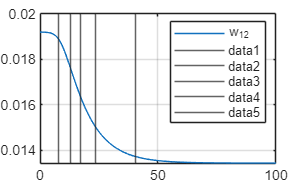

plot(times(1:end), w_12, DisplayName='w_{12}')
for i = 1:5
    % costruisci una funzione interpolante
    % risolvi t per cui interp1(t, w, t_query) = target
    % procedura: campiona densamente t e cerca primo crossing
    t_dense = linspace(times(1), times(end),length(times));
    w_dense = interp1(times, w_12, t_dense, 'pchip');
    idx = find(w_dense <= targets(i), 1); % se la curva decresce; altrimenti cerca >=

    if isempty(idx)
        t_targets(i,1) = NaN;
    else
        t_targets(i,1) = t_dense(idx);
    end
    hold on;
    xline(t_targets(i,1))
end
legend;
grid on;
hold off;

tau_e = 1./H_e_1;
tau_e_delta = max(tau_e)-min(tau_e);% valore iniziale
target1 = tau_e(1) - tau_e_delta * 0.05;
target2 = tau_e(1) - tau_e_delta * 0.28;
target3 = tau_e(1) - tau_e_delta * 0.5;
target4 = tau_e(1) - tau_e_delta * 0.72;
target5 = tau_e(1) - tau_e_delta * 0.95;

targets = [target1, target2, target3, target4, target5]

targets =     0.3060    0.2983    0.2908    0.2834    0.2757


t_targets = zeros(5,1)

t_targets =      0
     0
     0
     0
     0


plot(times(1:15000), tau_e(1:15000), DisplayName='\tau_e')
for i = 1:5
    % costruisci una funzione interpolante
    tau_ei = interp1(times, tau_e, 'pchip');  % non necessario come handle, vedi sotto
    
    % risolvi t per cui interp1(t, w, t_query) = target
    % procedura: campiona densamente t e cerca primo crossing
    t_dense = linspace(times(1), times(end), length(times));
    tau_e_dense = interp1(times, tau_e, t_dense, 'pchip');
    idx = find(tau_e <= targets(i), 1) % se la curva decresce; altrimenti cerca >=

    if isempty(idx)
        t_targets(i,1) = NaN;
    else
        t_targets(i,1) = t_dense(idx);
    end
    hold on;
    xline(t_targets(i,1))
end

idx = 2057

idx = 3937

idx = 5170

idx = 6556

idx = 9583

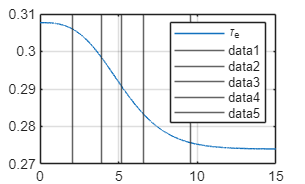

legend;
grid on;
hold off;


H_e_1(1)

ans = 3.2500

H_e_1(end)

ans = 3.6500

tau_i = C_ip_1./(1+exp(0.56 .* 0.1 .*(C_ip_1(1)-C_ip_1)));
tau_i_delta = max(tau_i)-min(tau_i);% valore iniziale
target1 = tau_i(1) - tau_i_delta * 0.05;
target2 = tau_i(1) - tau_i_delta * 0.28;
target3 = tau_i(1) - tau_i_delta * 0.5;
target4 = tau_i(1) - tau_i_delta * 0.72;
target5 = tau_i(1) - tau_i_delta * 0.95;

targets = [target1, target2, target3, target4, target5]

targets =    16.1908   13.0436   10.0332    7.0228    3.8755


t_targets = zeros(5,1)

t_targets =      0
     0
     0
     0
     0


plot(times(1:15000), tau_i(1:15000), DisplayName='\tau_i')
for i = 1:5
    % costruisci una funzione interpolante
    tau_ii = interp1(times, tau_i, 'pchip');  % non necessario come handle, vedi sotto
    
    % risolvi t per cui interp1(t, w, t_query) = target
    % procedura: campiona densamente t e cerca primo crossing
    t_dense = linspace(times(1), times(end), length(times));
    tau_i_dense = interp1(times, tau_i, t_dense, 'pchip');
    idx = find(tau_i <= targets(i), 1) % se la curva decresce; altrimenti cerca >=

    if isempty(idx)
        t_targets(i,1) = NaN;
    else
        t_targets(i,1) = t_dense(idx);
    end
    hold on;
    xline(t_targets(i,1))
end

idx = 2109

idx = 3980

idx = 5132

idx = 6328

idx = 8561

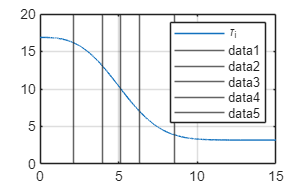

legend;
grid on;
hold off;


1/tau_i(1)

ans = 0.0593

1/tau_i(end)

ans = 0.3133


% % Plot di AB_1
% figure;
% plot(times,rho.*(w_12.*AB_2 - w_11.*AB_1), 'b-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('AB_1');
% 
% % Plot di ABtilde_1
% figure;
% plot(times, ABtilde_1, 'b-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('ABtilde_1');
% 
% % Plot di T_1
% figure;
% plot(times, T_1, 'g-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('T_1');
% 
% % Plot di Ttilde_1
% figure;
% plot(times, Ttilde_1, 'm-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('Ttilde_1');
% 
% % Plot di q_ha_1
% figure;
% plot(times, q_ha_1, 'c-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('q_ha_1');
% title('Evoluzione di q_{ha,1} nel modello di neurotossicità');
% 
% % Plot di H_e_1
% figure;
% plot(times, H_e_1, 'k-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('H_e_1');
% title('Evoluzione di H_e_1 nel modello di neurotossicità');
% 
% % Plot di C_ip_1
% figure;
% %plot(times, C_ip_1, 'b-', 'LineWidth', 2);
% %hold on;
% plot(times, -dt.*c_inh_ABtilde.*q_ABtilde_1.*(C_ep_1-C_ip_min), Color="r")
% hold on; 
% plot(times, -dt.*c_inh_Ttilde.*q_Ttilde_1.*(C_ep_1-C_ip_min), Color="g")
% hold off;
% grid on;
% xlabel('Time [years]');
% ylabel('C_ip_1');
% 
% % Plot di C_ep_1
% figure;
% plot(times, C_ep_1, 'm-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('C_ep_1');
% 
% % Plot di w_12
% figure;
% plot(times, w_12, 'm-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('w_12');
% 
% % Plot di q_ABtilde_1
% figure;
% plot(times, q_ABtilde_1, 'r-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('q_ABtilde_1');
% 
% % Plot di q_Ttilde_1
% figure;
% plot(times, q_Ttilde_1, 'r-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('q_Ttilde_1');
% 
% % Plot di AB_2
% figure;
% plot(times, AB_2, 'b-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('AB_2');
% 
% % Plot di ABtilde_2
% figure;
% plot(times, ABtilde_2, 'b-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('ABtilde_2');
% 
% % Plot di T_2
% figure;
% plot(times, T_2, 'g-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('T_2');
% 
% % Plot di Ttilde_2
% figure;
% plot(times, Ttilde_2, 'm-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('Ttilde_2');

% % Plot di q_ha_2
% figure;
% plot(times, q_ha_2, 'c-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('q_ha_2');
% title('Evoluzione di q_{ha,1} nel modello di neurotossicità');

% % Plot di H_e_2
% figure;
% plot(times, H_e_2, 'k-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('H_e_2');
% title('Evoluzione di H_e_1 nel modello di neurotossicità');
% 
% % Plot di C_ip_2
% figure;
% plot(times, C_ip_2, 'b-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('C_ip_2');
% 
% % Plot di C_ep_2
% figure;
% plot(times, C_ep_2, 'm-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('C_ep_2');

% % Plot di w_21
% figure;
% plot(times, w_21, 'm-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('w_21');
% 
% % Plot di w_11
% figure;
% plot(times, w_11, 'm-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('w_11');
% 
% % Plot di q_ABtilde_2
% figure;
% plot(times, q_ABtilde_2, 'r-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('q_ABtilde_2');
% 
% % Plot di q_Ttilde_2
% figure;
% plot(times, q_Ttilde_2, 'r-', 'LineWidth', 2);
% grid on;
% xlabel('Time [years]');
% ylabel('q_Ttilde_2');

limit_time = 20000;

% Plot di H_e_1 in confronto con H_e_2
 figure;
 plot(times(1: limit_time), H_e_1(1: limit_time), 'r-', 'LineWidth', 2);
 hold on;
 plot(times(1: limit_time), H_e_2(1: limit_time), 'g', 'LineWidth', 2);
 plot(times(1: limit_time), ones(limit_time,1).*(3.25 + (H_e_max-3.25)./10))
 plot(times(1: limit_time), ones(limit_time,1).*(3.25 + (H_e_max-3.25)./2))
 hold off;
 grid on;
 xlabel('Time [years]');
 ylabel('H_e');

 % Plot di C_ip_1 in confronto con C_ip_2
 figure;
 plot(times(1: limit_time), C_ip_1(1: limit_time), 'r-', 'LineWidth', 2);
 hold on;
 plot(times(1: limit_time), C_ip_2(1: limit_time), 'g', 'LineWidth', 2);
 plot(times(1: limit_time), ones(limit_time,1).*(33.75 - (33.75-13.25)./10))
 plot(times(1: limit_time), ones(limit_time,1).*(33.75 - (33.75-13.25)./2))
 hold off;
 grid on;
 xlabel('Time [years]');
 ylabel('C_{ip}');

  % Plot di C_ep_1 in confronto con C_ep_2
 figure;
 plot(times(1: limit_time), C_ep_1(1: limit_time), 'r-', 'LineWidth', 2);
 hold on;
 plot(times(1: limit_time), C_ep_2(1: limit_time), 'g', 'LineWidth', 2);
 plot(times(1: limit_time), ones(limit_time,1).*(108 - (108-28)./10))
 plot(times(1: limit_time), ones(limit_time,1).*(108 - (108-28)./2))
 hold off;
 grid on;
 xlabel('Time [years]');
 ylabel('C_{ep}');

  % Plot di w_11 in confronto con w_22, w_12 e w_21
 figure;
 plot(times, w_11, 'r-', 'LineWidth', 2);
 hold on;
 plot(times, w_22, 'g', 'LineWidth', 1);
 plot(times, w_21, 'b', 'LineWidth', 2);
 plot(times, w_12, 'yellow', 'LineWidth', 1);
 plot(times, ones(length(times),1).*(w_12(1) - (w_12(1)-w_12(end))./10))
 plot(times, ones(length(times),1).*(w_11(1) - (w_11(1)-w_11(end))./10))
 plot(times, ones(length(times),1).*(w_12(1) - (w_12(1)-w_12(end))./2))
 plot(times, ones(length(times),1).*(w_11(1) - (w_11(1)-w_11(end))./2))
 hold off;
 grid on;
 xlabel('Time [years]');
 ylabel('w_{ij}');

 figure;
 plot(times, w_21./max(w_12), 'r-', 'LineWidth', 2, 'DisplayName', 'w_{21}');
 hold on;
 plot(times, w_22./max(w_22), 'g', 'LineWidth', 1, 'DisplayName', 'w_{22}');
 plot(times, Ttilde_1./max(Ttilde_1), 'yellow', 'LineWidth', 2, 'DisplayName', 'T_{1t}');
 plot(times, Ttilde_2./max(Ttilde_2), 'b', 'LineWidth', 1, 'DisplayName', 'T_{2t}');
 plot(times, C_ep_2./max(C_ep_2), 'r-', 'LineWidth', 2, 'DisplayName', 'C_{ep,2}');
 plot(times, C_ep_1./max(C_ep_1), 'g', 'LineWidth', 1, 'DisplayName', 'C_{ep,1}');
 plot(times, C_ip_2./max(C_ip_2), 'yellow', 'LineWidth', 2, 'DisplayName', 'C_{ip,2}');
 plot(times, C_ip_1./max(C_ip_1), 'b', 'LineWidth', 1, 'DisplayName', 'C_{ip,1}');
 legend
 hold off;
 grid on;
 xlabel('Time [years]');
 title('\tau quantities')

 figure;
 plot(times, ABtilde_1./max(ABtilde_1), 'r-', 'LineWidth', 2, 'DisplayName', 'AB_{1t}');
 hold on;
 plot(times, ABtilde_2./max(ABtilde_2), 'g', 'LineWidth', 2, 'DisplayName', 'AB_{2t}');
 plot(times, H_e_1 ./max(H_e_1), 'yellow', 'LineWidth', 2, 'DisplayName', 'H_{e,1}');
 plot(times, H_e_2./max(H_e_2), 'b', 'LineWidth', 1, 'DisplayName', 'H_{e,2}');
 legend
 hold off;
 grid on;
 xlabel('Time [years]');
 title('A\beta quantities')